# SIMULAZIONE MODELLO CHIKUNGUNYA 

## Model Overview

## 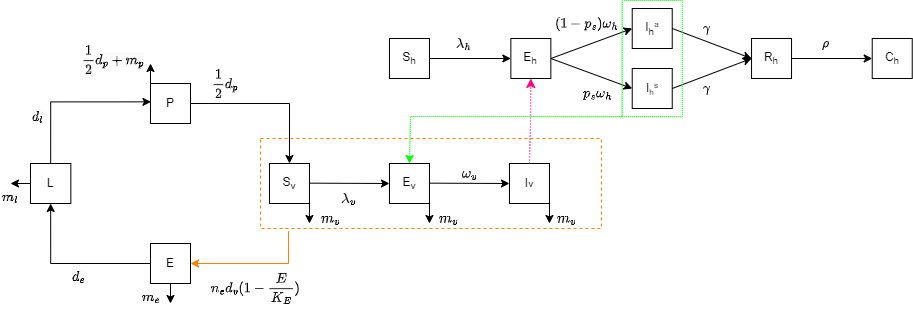

`Il grafo si può definire con 13 Equazioni differenziali del primo ordine `

- `SEIRC      Composto 6 ode -> Evoluzione Ospite`

- `SEI        Composto 3 ode -> Evoluzione Vettore `

- `ELPV       Composto 4 ode -> Riproduzione Vettore`

### `SEIRC`    

$\dot{\frac{dS_u }{dt}={-\lambda }_h S_u }$                                   dove     $\lambda_h= ab_h\frac{I_v}{N_h}$


$$\frac{dE_h }{dt}=\lambda_h S_h \;-\omega_h E_h$$



$$\frac{dI_h^a }{dt}=p_s \;\omega_{h\;} E_h \;-\gamma I_h^a$$



$$\frac{dI_h^s }{dt}=\left(1-p_s \right)\;\omega_{h\;} E_h \;-\gamma I_h^s$$



$$\frac{dR_h }{dt}=\gamma \left(I_h^s +I_h^a \right)\;-\rho R_h$$



$$\frac{dC_h }{dt}=\rho R_h \;$$


### `SEI`

$\frac{dS_z}{dt}=
\frac{1}{2}d_pP \;-m_vS_v  \;-\lambda_vS_v $           dove     $\lambda_v = ab_v\frac{I_h^a+I_h^s}{N_h} $


$$\frac{dE_v}{dt}=
\lambda_vS_z \;-m_vE_v -\omega_v E_v
$$



$$\frac{dI_v}{dt}=\omega_v E_v-m_vI_v$$


### `ELPV`


$$\frac{dE}{dt} = n_Ed_v(1-\frac{E}{K_E})V-m_eE -d_eE $$



$$\frac{dL}{dt} = d_eE -m_lL -d_lL$$



$$\frac{dP}{dt} = m_l L -m_pP -d_pP$$


$\frac{dV}{dt} = \frac{1}{2}d_pP-m_vV$                        `dove`     $V=S_v+E_v+I_v$

## `Simulazione Modello`

### Variazione Temperatura

    Raccogliamo in dei vettori rispettivamente:

                - Il mese di riferimento e i giorni associati

                - La temperatura media mensile di riferimento

                - la deviazione in gradi di temperatura dalla media di riferimento

    per ogni mese andiamo a sporcare la temperatura secondo una gaussiana 

    andiamo infine a calcolare la curva di interpolazione tramite il comando fit

    il risultato di queste operazioni consiste in una curva interpolante che cerca di approssimare l'andamento della temperatura annuale.

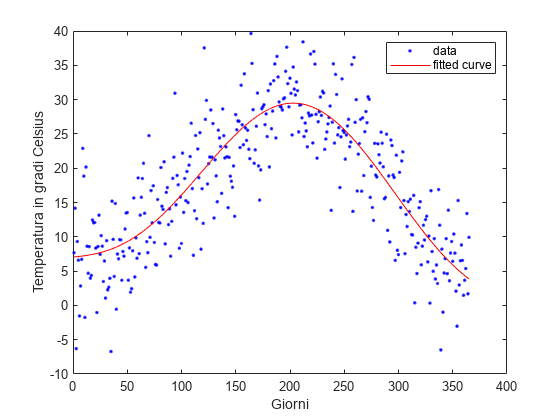

global fitresult
% Temperature medie Emilia-Romagna ultimi 30 anni 
%       Gen  Feb  Mar  Apr  Mag  Giu  Lug  Ago  Set  Ott  Nov  Dic
mesi = [ 1,   2,   3,   4,   5,   6,   7,   8,   9,  10,  11,  12];
Tmed = [ 5,   8,  13,  18,  23,  27,  30,  29,  25,  19,  11,   6]; [min_Tmax,max_Tmax] = bounds(Tmed);
del  = [ 5,   5,   5,   5,   5,   5,   5,   5,   5,   5,   5,   5];
giorni=[31,  28,  31,  30,  31,  30,  31,  31,  30,  31,  30,  31]; 
%  TEMPERATURE GIORNALIERE
temperatura_giorni = [];
for i=1:12
    temperatura_media_mensile = Tmed(i);
    dev = del(i); 
    numero_giorni = giorni(i);
    temperatura_giorni =[temperatura_giorni, temperatura_media_mensile + dev * randn(1, numero_giorni)];
end
% INTERPOLAZIONE
V = double(1):double(sum(giorni));
[xData, yData] = prepareCurveData( V, temperatura_giorni );
ft = fittype( 'sin2' );
[fitresult, gof] = fit( xData, yData, ft);
h = plot(fitresult,  xData, yData );
xlabel('Giorni'); 
ylabel('Temperatura in gradi Celsius');

#### `FUNZIONE TROVATA`

`    stampa a schermo l'espressione della curva trovata nella sezione precedente e i relativi coefficienti.`

disp(fitresult);

     General model Sin2:
     fitresult(x) =  a1*sin(b1*x+c1) + a2*sin(b2*x+c2)
     Coefficients (with 95% confidence bounds):
       a1 =       23.44  (15.92, 30.97)
       b1 =    0.006287  (0.00235, 0.01022)
       c1 =      0.4042  (-0.5154, 1.324)
       a2 =       6.228  (-1.07, 13.53)
       b2 =     0.02085  (0.01164, 0.03005)
       c2 =       3.497  (1.504, 5.49)


#### PARAMETRI

- PARAMETRI GLOBALI

- CICLO DI VITA ZANZARE           

- DINAMICA INFEZIONE VETTORE 

- DINAMICA INFEZIONE OSPITE

## **PARAMETRI GLOBALI**

### `    POLAZIONE TOTALE DEGLI OSPITI E VETTORI`

% NUMERO TOTALE OSPITI %        % NUMERO TOTALE VETTORI %
Nh  = 60000;                    rap = 20; % Rapporto zanzare/uomo 
                                Nv  = rap*Nh; 

### `    PERIODO DI INTEGRAZIONE`

% INIZIO PERIODO VALUTAZIONE %      % FINE PERIODO VALUTAZIONE %
% IN GIORNI %                       % IN GIORNI %
Inizio_Valutazione  = 100;            Fine_Valutazione    = 365; 

tspan =  [Inizio_Valutazione   Fine_Valutazione  ]; % In GIORNI

### `    MODELLO CON CONTROLLO PREDA - PREDATORE`

controllo = 0;

## DINAMICA VETTORE - ZANZARA

### `    MORTALITA' STADI VETTORE`

I tassi di mortalità delle zanzare sono espressi come funzioni che dipendono dalla temperatura. 

È stata creata una funzione denominata temp(t), dove il tempo t viene utilizzato come parametro di ingresso. 

Grazie alla curva di interpolazione precedentemente creata, siamo in grado di determinare la temperatura specifica nel momento t.    

        
$$m_E\,(T)\,= p_1-p_2 \;e^{\frac{(T-25)^6}{p_3}}
$$
           
$$p_1=506$$
           
$$p_2=506$$
           
$$p_3= 27.3
$$


                
$$m_L \, (T) \, = p_1+p_2 \;e^{T-p_3}$$
              
$$p_1= 0.029
$$
        
$$p_2=858$$
           
$$p_3=43.4
$$


                
$$m_P \, (T) \, = p_1+p_2 \;e^{T-p_3}$$
              
$$p_1=0.021
$$
        
$$p_2=37
$$
             
$$p_3=36.8
$$


                
$$m_V \, (T) \, = p_1+p_2 \;e^{T-p_3}$$
              
$$p_1=0.031
$$
        
$$p_2=95820$$
       
$$p_3=50.4$$


tassi = m_rate(Inizio_Valutazione);
        m_E = tassi (1);
        m_L = tassi (2);
        m_P = tassi (3);
        m_V = tassi (4);

### `    SVILUPPO STADI VETTORE`

                
$$d_e (T)=p_1-p_2 e^{-(\frac{(T-20)}{p_3} )^2 $$
                          
$$p_{1e} = 6.9;   \;\;\;\; p_{2e} =  4.0; \;\;\    p
_{3e} =  4.1;$$


                
$$d_l (T)=p_1 T^2-p_2 T+p_3$$
                           
$$p_{1l} = 0.12;   \;\;\  p_{2l} = -6.6;    \;\;\; p_{3l} = 98;$$


                
$$d_P (T)=p_1 T^2-p_2 T+p_3 
$$
                          
$$ p_{1P} = 0.027;\;\;\;   p_{2P} = -1.7;   \;\;\;  p_{3P} = 27.7;$$


                
$$d_v (T)=p_1 T^2-p_2 T+p_3
$$
                          
$$ p_{1V} = 0.046; \;\;\;  p_{2V} = -2.77;  \;\;\;  p_{3V} = 45.3;$$


        p1_E = 6.9;      p2_E =  4.0;     p3_E =  4.1;
        p1_L = 0.12;     p2_L = -6.6;     p3_L = 98;
        p1_P = 0.027;    p2_P = -1.7;     p3_P = 27.7;
        p1_V = 0.046;    p2_V = -2.77;    p3_V = 45.3;
% TASSO DI SVILUPPO IN FUNZIONE DELLA TEMPERATURA
develop = d_rate(Inizio_Valutazione);    
    d_V = develop(1);    % Sviluppo Adulti      
    d_E = develop(2);    % Sviluppo Uova        
    d_L = develop(3);    % Sviluppo Larve       
    d_P = develop(4);    % Sviluppo Pupae       

### `    PARAMETRI OVIDEPOSIZIONE`

% PARAMETRI SU OVIDEPOSIZIONE
    n_E = 75;           % Numero di uova per ovideposione -> range [50    - 75]
    Ke  = 260000;           % Capacità di carico uova         -> range [66500 - 266000] 

### `    PREDATORE`

    r = 0.01;                         % tasso di crescita
    c = 0.1;                          % convenction efficiency
    Kp = 1000;                        % capacità trasporto pesce
    H  = 0.8;                         % harvesting effort catching fish region 1
    q  = 0.2;                         % catchability fish 
    alpha_1 = 0.1;                    % dipendenza lineare della caccia 
    alpha_2 =0.3;                     % frazione di pesci che vengono trasportati dalla regione 1 a regione 2
    ni  = 0.1;                        % densità della regione 1
    m_d = 0.01;                       % Mortalità per densità

    param_PRED = [r,c,Kp,H,q,alpha_1,alpha_2,ni]; 

## **DINAMICA INFEZIONE **

### `    DINAMICA INFEZIONE OSPITE `$\Rightarrow$` VETTORE `

a       = 0.25;           % Tasso morsi in Europa

b_V     =0.9;       % Probabilità trasmissione uomo infetto -> zanzara suscettibile [70 - 100]

omega_V = 1/2;           % 1/omega Periodo di incubazione in giorni [2 - 3]

### `    DINAMICA INFEZIONE VETTORE `$\Rightarrow

$` OSPITE `

% Parametro del tasso di morso condiviso con la dinamica ospite -> vettore 

b_h     = 0.6;      % Probabilità trasmissione vettore infetto -> uomo suscettibile  [50 - 80]%
omega_h = 1/3;           % 1/omega Periodo di incubazione in giorni [2 - 4]
ps      = 0.5;      % Probabilità di sviluppare sintomi
gamma   = 1/15;                             % 1/gamma Periodo di infezione [15] giorni
rho_h   = 1/300*0.1;                        % 1/rho_h Tempo di cronicizzazione malattia [300] giorni 
                                            % 10% di probabilità di cronicizzazione       

## CONDIZIONI INIZIALI

% SEIRC - Ospite
Sh0 = Nh-200;  Eh0 = 0;  Iah0 = 200; Ish0 = 0;  Rh0 = 0; Ch0 = 0; 

% SEI - Vettore
Sv0 = Nv-800;  Ev0 = 0; Iv0 = 800;

% Ciclo Vita Vettore
E0 =1000; L0=2000; P0=3000;

% Predatore
Pe0 = 10;

% Raccolgo in forma vettoriale 
if controllo == 0  % Se non considero controllo biologico trascuro le condizioni iniziali dei predatori
    y0 = [Sh0; Eh0; Iah0; Ish0; Rh0; Ch0; Sv0; Ev0; Iv0; E0; L0; P0]; 

else
    y0 = [Sh0; Eh0; Iah0; Ish0; Rh0; Ch0; Sv0; Ev0; Iv0; E0; L0; P0; Pe0];
end 


## Risoluzione equazioni differenziali con ode45

if controllo == 0   % Richiamo la funzione senza Controllo biologico
    [t,y] = ode45(@(t,y) seir(t,y, Nh,a,b_V,omega_V,b_h,omega_h,ps,gamma,rho_h,n_E,Ke),tspan,y0);

else                % Richiamo la funzione con Controllo biologico
    [t,y] = ode45(@(t,y) seir_ctrl(t,y, Nh,a,b_V,omega_V,b_h,omega_h,ps,gamma,m_d,rho_h,n_E,Ke,r,c,Kp,H,q,alpha_1,alpha_2,ni),tspan,y0);
end

## `DEBUG TASSI DI SVILUPPO - MORTE`

tax_mort = [] ;
tax_dev =[];
for i=Inizio_Valutazione:Fine_Valutazione
     M = m_rate(i);
     D = d_rate(i);
    tax_mort = [tax_mort; M];
    tax_dev  = [tax_dev ; D];
end

## GRAFICI DINAMICHE

### CALCOLO VARIAZIONI NUMERO OSPITI E VETTORI DURANTE L'INFEZIONE

% NUMERO OSPITI NEL PERIODO CONSIDERATO %           % NUMERO VETTORI NEL PERIODO CONSIDERATO %
Nh_r = y(:,1)+y(:,2)+y(:,3)+y(:,4)+y(:,5)+y(:,6);   Nv_r = y(:,7)+y(:,8)+y(:,9);

### ***MODELLO SEIRC - OSPITE***

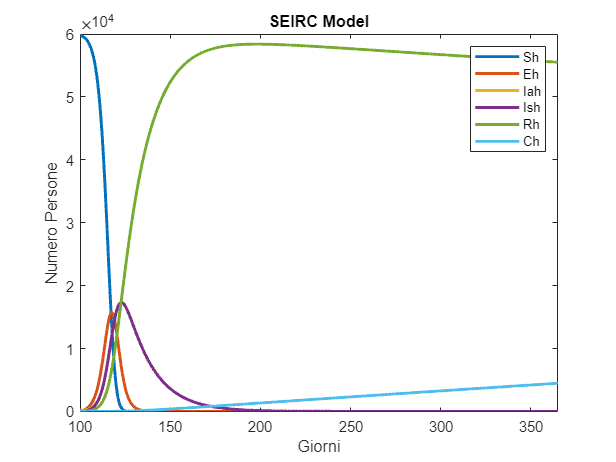

figure()
plot(t,y(:,1:6),'LineWidth',2);
xlabel('Giorni'); 
ylabel('Numero Persone');
legend('Sh','Eh','Iah','Ish','Rh','Ch');
title('SEIRC Model');
xlim([Inizio_Valutazione   Fine_Valutazione ]);

### **MODELLO SEI - VETTORE**

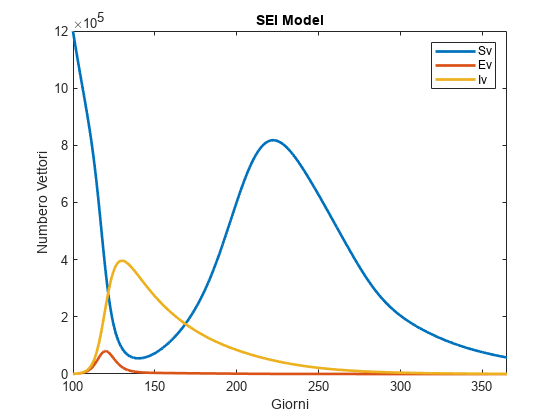

figure()
plot(t,y(:,7:9),'LineWidth',2);
xlabel('Giorni'); 
ylabel('Numbero Vettori');
legend('Sv','Ev','Iv');
title('SEI Model');
xlim([Inizio_Valutazione   Fine_Valutazione ]);

### MODELLO ELPV - CICLO DI VITA VETTORE

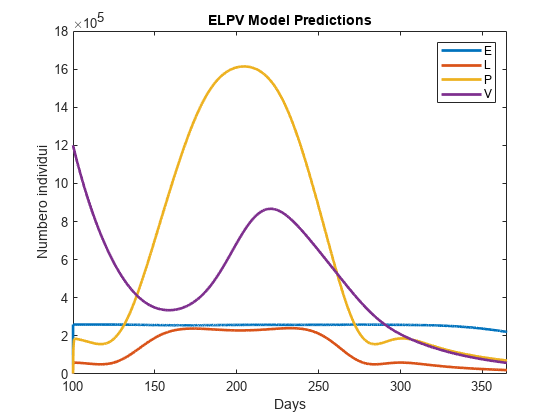

figure()
plot(t,y(:,10:12),'LineWidth',2); hold on;
plot(t,Nv_r,'LineWidth',2);
xlabel('Days'); 
ylabel('Numbero individui');
legend('E','L','P','V');
title('ELPV Model Predictions');
xlim([Inizio_Valutazione   Fine_Valutazione ]);

if controllo == 1
    figure()
    plot(t,y(:,11),'LineWidth',2); hold on;
    plot(t,y(:,13),'LineWidth',2); 

    xlabel('Days'); 
    ylabel('Number of individuals');
    legend('L','Pe');
    title('prey predator');
    grid on
end

## `Numero di Riproduzione di base`

`R0 è un termine usato in epidemiologia per indicare la capacità di diffusione di una malattia infettiva non controllata. Rappresenta il numero medio di nuovi casi generati da un individuo infetto durante il suo periodo di contagiosità. Esprime il numero previsto di nuove infezioni derivanti da un singolo individuo in una popolazione suscettibile, all'inizio di un'epidemia o in assenza di misure di controllo del contagio.`

2 metodi di calcolo

- Next Generation Matrix

- `Caso a singoli Vettori`

### [`Next Generation Matrix (NGM)`](https://www.zoology.ubc.ca/let/pdfs/Diekmann2010.pdf)

`Se impostiamo `$x = (E_h, \;I_h, \;E_v, \;I_v)^T$` vogliamo ora scrivere il sottosistema di infezione linearizzato nella forma:`

                                                 
$$\dot{\;x} =\left(T+\Sigma \right)x$$


`La matrice di trasmissione `$T$`, indica il passaggio del patogeno tra tutte le fasi del sottosistema di infezione.`

                                          
$$T=\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & \beta_1 \\
0 & 0 & 0 & 0\\
0 & \beta_2  & 0 & 0\\
0 & 0 & 0 & 0
\end{array}\right\rbrack$$


`La matrice di transizione `$\Sigma$`, indica tutte le altre transizioni da e verso il sottosistema di infezione.`

                 
$$\Sigma =\left\lbrack \begin{array}{cccc}
{-\omega }_h  & 0 & 0 & 0\\
\omega_h  & -\gamma  & 0 & 0\\
0 & 0 & -\left(m_{v\;} \omega_v \right) & 0\\
0 & 0 & \omega_v  & {-m}_v 
\end{array}\right\rbrack$$


`la NGM sarà quindi definita come:`

                            
$$K=-T\Sigma^{-1}$$


`l'indice `$R_0$` si ricava dal raggio spettrale di `$K$

                                                      
$$R_0=\rho(K)$$


beta_1 = a*b_h*(Nv/Nh);
beta_2 = a*b_V;

T = [ 0     0      0     beta_1;
      0     0      0        0;
      0   beta_2   0        0;
      0     0      0        0];

SIGMA = [ -omega_h      0       0        0 ;
           omega_h   -gamma     0        0 ;
              0         0 -(m_V+omega_V) 0 ;
              0         0    omega_V   -m_V];

SIGMA_inv = inv(SIGMA);

R0_GM = max(abs(eig(-T*SIGMA_inv)));


### `CASO SINGOLI VETTORI`

`La media del numero di ospiti infettati direttamente dall'introduzione di un singolo vettore infettivo in una popolazione di ospiti completamente suscettibili è determinata dalla probabilità di trasmissione (`$ab_h$`) moltiplicata dalla durata dell'infezione del vettore adulto (cioè l'intera durata della vita) `$
\frac{1}{m_a}
$`.`

                                                 
$$R_0^{VH}=\frac{ab_h}{m_v}$$
 

`Il numero medio di vettori infettati da un singolo ospite infetto dipende dalla probabilità di trasmissione, dal numero iniziale di zanzare per umano e dal periodo di latenza e di contagiosità umana. Questo valore rappresenta la potenziale diffusione dell'infezione in una popolazione di vettori completamente suscettibili.`

                                   
$$R_0^{HV}=ab_v \; \frac{Nv}{Nh} \; \frac{\omega_v}{\omega_v+m_V} \; \frac{1}{\gamma}$$


                         
$$R_0 = R_0^{HV}\cdot R_0^{VH} = a^2 bvb_h \;\frac{N_v}{N_h}\;\frac{\omega_v}{\omega_v+m_V} \; \frac{1}{\gamma m_V}$$


R0VH = a*b_h/m_V;
R0HV = a*b_V *(Nv/Nh) * (omega_V/(omega_V+m_V)) * 1/gamma;

R0_SV = R0HV*R0VH;

### `Probabilità che si verifichi un'epidemia importante della malattia dopo l'introduzione di un singolo ospite infetto `

probability = 1 - (R0VH+1)/(R0VH*(R0HV)+1);
fprintf(" Probabilità di epidemia " ); disp(probability);

 Probabilità di epidemia     0.9811



 Probabilità di epidemia   Columns 1 through 10

    0.9811   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387

  Columns 11 through 20

   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387

  Columns 21 through 30

   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387

  Columns 31 through 40

   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387

  Columns 41 through 50

   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387

  Columns 51 through 60

   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387

  Columns 61 through 70

   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387

  Columns 71 through 80

   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387   -4.8387  

### `Andamento Numero totale vettori e ospiti `

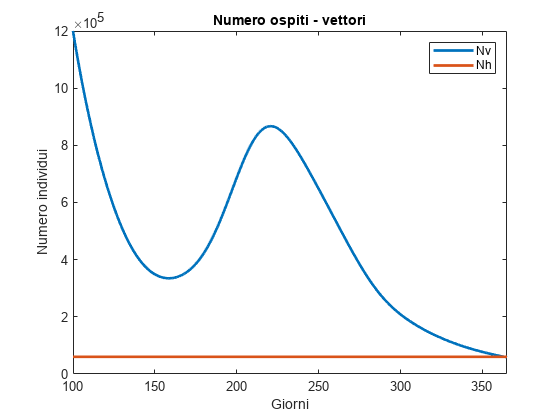

figure()
plot(t,Nv_r,'LineWidth',2); hold on;
plot(t,Nh_r,'LineWidth',2);
xlabel('Giorni'); 
ylabel('Numero individui');
legend('Nv','Nh');
title('Numero ospiti - vettori');
xlim([Inizio_Valutazione   Fine_Valutazione ]);
hold off;

### `Grafico indice R0`


$$R_0 =  a^2 bvb_h \;\frac{N_v}{N_h}\;\frac{\omega_v}{\omega_v+m_V} \; \frac{1}{\gamma m_V}$$



$$Rapp = \frac{N_v}{N_h}$$
           
$$


R_o =  a^2 bvb_h \;\frac{\omega_v}{\omega_v+m_V} \; \frac{1}{\gamma m_V}$$
     

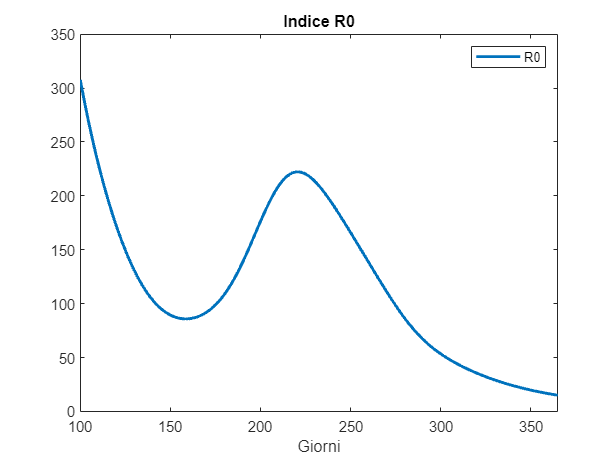

Rapp = Nv_r./Nh_r;      Ro = a*a *b_V*b_h * (omega_V/(omega_V+m_V))*(1/(gamma*m_V));
figure()
plot(t,Ro*Rapp,'LineWidth',2);
xlabel('Giorni'); 
ylabel('');
legend('R0');
xlim([Inizio_Valutazione   Fine_Valutazione ]);
title('Indice R0');

### Attendibilità dei risultati:

I due metodi proposti differiscono nel calcolo dell'indice R0. 

Nel primo metodo, l'indice R0 viene calcolato utilizzando la matrice della "Next Generation" (matrice NGM), mentre nel secondo metodo viene utilizzato il "metodo del singolo vettore". 

Una differenza significativa. il valore con NGM è pari alla radice quadrata del metodo singolo vettore.

     fprintf("R0 Single Vector " ); disp(R0_SV);

R0 Single Vector   307.5451



     fprintf("R0 NGM al quadrato "); disp(R0_GM*R0_GM);

R0 NGM al quadrato   307.5451



###     ANALISI SENSIBILITA' PARAMETRICA

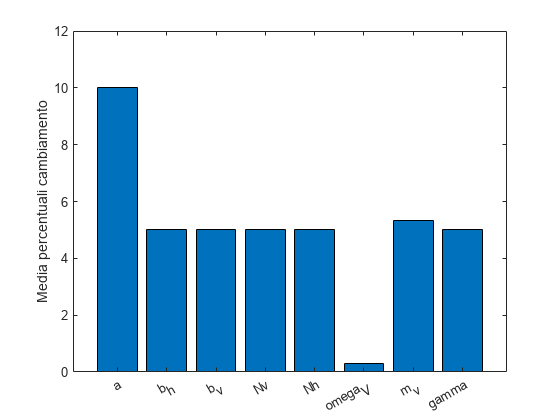

 var = 10;  % percentuale 
 N = 1000000;   % Numero campioni

 param_1 = a         ;%*  [(1-var/100) (1+var/100)];
 param_2 = b_h       ;%*  [(1-var/100) (1+var/100)];
 param_3 = b_V       ;%*  [(1-var/100) (1+var/100)];
 param_4 = Nv        ;%*  [(1-var/100) (1+var/100)];
 param_5 = Nh        ;%*  [(1-var/100) (1+var/100)];
 param_6 = omega_V   ;%*  [(1-var/100) (1+var/100)];
 param_7 = m_V       ;%*  [(1-var/100) (1+var/100)];
 param_8 = gamma     ;%*  [(1-var/100) (1+var/100)];

val_prova=[];
parametri_riferimento = [a, b_h, b_V, Nv, Nh, omega_V, m_V, gamma];
num_parametri = size(parametri_riferimento,2);

% Inizializzazione delle percentuali di cambiamento
percentuali_cambiamento = zeros(N, num_parametri);
R_norm = index(parametri_riferimento(1), parametri_riferimento(2), parametri_riferimento(3), parametri_riferimento(4), parametri_riferimento(5), parametri_riferimento(6),parametri_riferimento(7),parametri_riferimento(8));
media_percentuali_cambiamento=zeros(1,num_parametri);

for i=1:num_parametri
    val_prova = transpose( linspace( eval("param_"+ num2str(i))*(1-var/100),eval("param_"+num2str(i))*(1+var/100),N));
    parametri = parametri_riferimento;
    for j=1:N
        %calcolo R_nuovo
        parametri(i) = val_prova(j);
        R_sens = index(parametri(1), parametri(2), parametri(3), parametri(4), parametri(5), parametri(6),parametri(7),parametri(8));
        
        percentuale_cambiamento = abs((R_sens - R_norm) / R_norm) * 100;
        percentuali_cambiamento(j,i) = percentuali_cambiamento(j,i) + percentuale_cambiamento;
    
    end
    % Calcolo della media delle percentuali di cambiamento per il parametro corrente
    media_percentuali_cambiamento(i) = sum(percentuali_cambiamento(:,i)) / N;
end
X=categorical({'a','b_h','b_v','Nv','Nh','omega_V','m_v','gamma'});
X=reordercats(X,{'a','b_h','b_v','Nv','Nh','omega_V','m_v','gamma'});
bar(X,media_percentuali_cambiamento);
ylabel('Media percentuali cambiamento');

### Funzione - Calcolo Indice R0

usato nell'analisi di sensitività per calcolare iterativamente esplorando un parametro alla volta 

` Inputs:`

- `    a,b_h,b_V,Nv,Nh,omega_V, m_V, gamma                parametri già trattati nella sezione apposita`

` Output:`

- `    index            Valore di `$R_0$ per quei parametri

function g = index(a,b_h,b_V,Nv,Nh,omega_V, m_V, gamma )
g = a*a *b_V*b_h *(Nv/Nh)* (omega_V/(omega_V+m_V))*(1/(gamma*m_V));
 
end

### Funzione temperatura

` Inputs:`

- `    x                tempo`

` Output:`

- `    a                temperatura media associata al tempo x`

function a = temp(x) 
       global fitresult
       a = fitresult(x); 
end

### Funzione - Calcolo dei tassi di morte 

` Inputs:`

- `    t                tempo`

` Output:`

- `    tassi            array contenente tassi di morte delle zanzare nelle varie fasi`

function mortality_rate = m_rate(t)
 
       % DETERMINO TEMPERATURA ALL'ISTANTE t
        y = temp(t);
      
       % COEFF. DELLE ESPRESSIONI 
        p1_E = 506;      p2_E = 506;      p3_E = 27.3;
        p1_L = 0.029;    p2_L = 858;      p3_L = 43.4;
        p1_P = 0.021;    p2_P = 37;       p3_P = 36.8;
        p1_V = 0.031;    p2_V = 95820;    p3_V = 50.4;

       % MORTALITA' DEGLI STADI DELLA ZANZARA IN FUNZIONE DELLA TEMPERATURA 
        m_E = p1_E -p2_E *exp(-((y-25)/p3_E).^6);
        if m_E < 0
            m_E = 0;
        end
        m_L = p1_L +p2_L *exp(y-p3_L);
        if m_L < 0
            m_L = 0;
        end
        m_P = p1_P +p2_P *exp(y-p3_P);
        if m_P < 0
            m_P = 0;
        end
        m_V = p1_V +p2_V *exp(y-p3_V);
        if m_V < 0
            m_V = 0;
        end
       % RACCOLGO I DATI IN UN ARRAY
        mortality_rate=[m_E , m_L, m_P, m_V];
        
end

### Funzione - Calcolo dei tassi di morte 

` Inputs:`

- `    t                tempo`

` Output:`

- `    develop_rate            array contenente tassi di sviluppo delle zanzare nelle varie fasi`

function develop_rate = d_rate(t)
 
        y =  temp(t);
      
        % temperatura iniziale temperatura_giorni(1)
        p1_E = 6.9;      p2_E =  4.0;     p3_E =  4.1;
        p1_L = 0.12;     p2_L = -6.6;     p3_L = 98;
        p1_P = 0.027;    p2_P = -1.7;     p3_P = 27.7;
        p1_V = 0.046;    p2_V = -2.77;    p3_V = 45.3;

        % MORTALITA' DEGLI STADI DELLA ZANZARA IN FUNZIONE DELLA TEMPERATURA 
        % Temp iniziale (1 gennaio)
        d_E = p1_E -p2_E *exp(-((y-20)/p3_E).^2);
        if d_E < 0
            d_E = 0;
        end
        d_L = p1_L*y^2 +p2_L*y + p3_L;
        if d_L < 0
            d_L = 0;
        end
        d_P = p1_P*y^2 + p2_P*y + p3_P;
        if d_P < 0
            d_P = 0;
        end
        d_V = p1_V*y^2 +p2_V*y + p3_V;
        if d_V < 0
            d_V = 0;
        end
        develop_rate=[d_E , d_L, d_P, d_V];

end

## Funzioni dei Modelli SEIRC - SEI - ELPV senza controllo biologico

function dydt = seir(t,y,Nh, a, b_V, omega_V, b_h, omega_h, ps, gamma, rho_h, n_E, Ke)
   
    M = m_rate(t);
    D = d_rate(t);
        
    Sh = y(1);  Eh = y(2);  Iah = y(3);  Ish = y(4);  Rh = y(5);  Ch = y(6);
    Sv = y(7);  Ev = y(8);  Iv = y(9);
    E  = y(10); L = y(11);  P = y(12);
    
    %% DINAMICA INFEZIONE OSPITE - UOMO %%                          
        dSh   = -(a*b_h*Iv/Nh)*Sh ;                                
        dEh   = (a*b_h*Iv/Nh)*Sh  -omega_h*Eh ;                   
        dIah  = ps*omega_h*Eh  -gamma*Iah ;                       
        dIsh  = (1 - ps)*omega_h*Eh  -gamma*Ish ;                 
        dRh   = gamma*(Iah+Ish)  -rho_h*Rh ;                      
        dCh   = rho_h*Rh ;   

   %% DINAMICA INFEZIONE VETTORE - ZANZARA %%
        dSv = 0.5*M(3)*P  -M(4)*Sv  -(a*b_V*(Iah+Ish)/Nh)*Sv;      
        dEv = (a*b_V*(Iah+Ish)/Nh)*Sv  -M(4)*Ev  -omega_V*Ev;      
        dIv = omega_V*Ev  -M(4)*Iv;     

    %% DINAMICA VETTORE - ZANZARA %%                                                  
        dE = n_E*D(4)*(1-(E/Ke))*(Sv+Ev+Iv)  -M(1)*E  -D(1)*E;      
        dL = D(1)*E  -M(2)*L  -D(2)*L;                   
        dP = D(2)*L  -M(3)*P  -D(3)*P;      
    
    %% OUTPUT           
   dydt = [dSh; dEh; dIah; dIsh; dRh; dCh; dSv; dEv; dIv; dE; dL; dP];
end

## Funzioni dei Modelli SEIRC - SEI - ELPV  con controllo biologico

function dydt = seir_ctrl(t,y,Nh,a,b_V,omega_V,b_h,omega_h,ps,gamma,m_d,rho_h,n_E, Ke,r,c,Kp,H,q,alpha_1,alpha_2,ni)
    
    M = m_rate(t);
    D = d_rate(t);

    Sh = y(1);  Eh = y(2);  Iah = y(3);  Ish = y(4);  Rh = y(5);  Ch = y(6);
    Sv = y(7);  Ev = y(8);  Iv = y(9);
    E  = y(10); L = y(11);  P = y(12);
    Pe = y(13);

    %% DINAMICA INFEZIONE OSPITE - UOMO %%                          
        dSh   = -(a*b_h*Iv/Nh)*Sh ;                                
        dEh   = (a*b_h*Iv/Nh)*Sh  -omega_h*Eh ;                   
        dIah  = ps*omega_h*Eh  -gamma*Iah ;                       
        dIsh  = (1 - ps)*omega_h*Eh  -gamma*Ish ;                 
        dRh   = gamma*(Iah+Ish)  -rho_h*Rh ;                      
        dCh   = rho_h*Rh ;   
   %% DINAMICA INFEZIONE VETTORE - ZANZARA %%
        dSv = 0.5*M(3)*P  -M(4)*Sv  -(a*b_V*(Iah+Ish)/Nh)*Sv;      
        dEv = (a*b_V*(Iah+Ish)/Nh)*Sv  -M(4)*Ev  -omega_V*Ev;      
        dIv = omega_V*Ev  -M(4)*Iv;     

   %% DINAMICA VETTORE - ZANZARA %%                                                  
        dE = n_E*D(4)*(1-(E/Ke))*(Sv+Ev+Iv)  -M(1)*E  -D(1)*E;      
        dL = D(1)*E  -M(2)*L  -D(2)*L -m_d*L*L -alpha_1*L*ni   -alpha_2*alpha_1*L*(1-ni)*q*H*Pe;                   
        dP = D(2)*L  -M(3)*P  -D(3)*P;   
       
    %% PREDATORE
        dPe = r*Pe*(1-Pe/Kp)  + c*alpha_1*L*ni*Pe   -q*H*Pe;
    %% OUTPUT     
   dydt = [dSh;dEh;dIah;dIsh;dRh;dCh;dSv;dEv;dIv;dE;dL;dP;dPe];
end